**Exercise 1**

Try to solve the following differential equation


$$\frac{d^2 \theta \;}{{\textrm{dx}}^2 }=\frac{T}{\textrm{GJ}\left(\theta \right)}$$


where:


$$J\left(\theta \right)=J_0 \left(1+k\theta^2 \right)$$


Boundary Conditions:


$$\theta_0 =0$$



$$\theta_L =1\;\textrm{rad}$$


and given parameters:


$$\begin{array}{l}
G=2\cdot {10}^8 \\
T=50\\
J_0 =2\ldotp 4\cdot {10}^{-7} \\
k=5\cdot {10}^{-4} \\
L=1\ldotp 5
\end{array}$$


Hint: You may start with the code written for the penfulum in Lecture 5, Exercise 2.

clc; clear variables; close all;

% Boundary Conditions
theta0 = 0;          % Theta at begining of the shaft
thetaL = 1;          % Theta at the end of the shaft

% Initial guess for ThetaDot at begining of the shaft
Zeta1  = -0.5;
Zeta2  = -0.1;

Y0_1 = [theta0 ; Zeta1];
Y0_2 = [theta0 ; Zeta2];

% time
dx = 0.01;           % Delta x
x  = 0:dx:1.5;
nx = length(x);

% solve

% Initial parameters for the Root Finding
Y = odesRK4(@ODEfun,Y0_1,x);
g(1)= Y(1,nx)-thetaL;

Y = odesRK4(@ODEfun,Y0_2,x);
g(2)= Y(1,nx)-thetaL;

er  = 1e-5;
i   = 2;
Zn  = Zeta2;
Zn_1= Zeta1;

while abs(g(i))>er %&& i<50

        gn   = g(i)
        gn_1 = g(i-1)
        i    = i+1

        Zeta = Zn-(gn/((gn-gn_1)/(Zn-Zn_1)));          % Secant Method
        Y0   = [theta0 ; Zeta];
        Y    = odesRK4(@ODEfun,Y0,x);                        
        g(i) = Y(1,nx) - thetaL
        Zn_1 = Zn;
        Zn   = Zeta;

end

gn = 0.0218

gn_1 = -0.5781

i = 3

g =    -0.5781    0.0218    0.0000


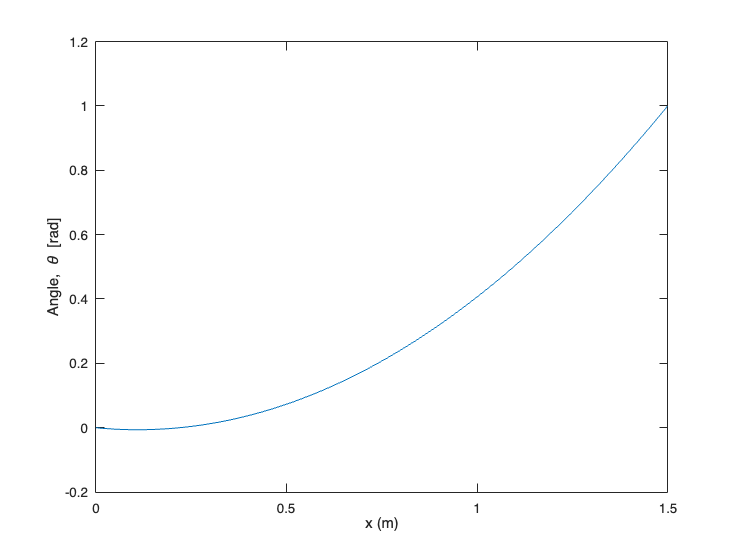


theta= Y(1,:);

% plot results
figure
plot(x,theta)
xlabel('x (m)');
ylabel('Angle, \theta [rad]')




function f = ODEfun(Y_ins,x)
% Returns derivatives of Y at x
% Y_ins = [theta; ttDot]              The 2*1 input vector at each moment
% f = [d_theta/dt; d_ttDot/dt]        The vector ODE functions at Y and x

    % rename back
    Y1 = Y_ins(1);
    Y2 = Y_ins(2);

    T  = 50;                     % applied torque
    G  = 2e8;                    % shear modulus 
    J0  = 2.4e-7;                % initial polar moment of inertia 
    k = 5e-4;                    % constant

    
    f1 = Y2;                     % value of first ODE function
    f2 = T/(G*J0*(1+k*Y1^2));    % value of second ODE function
    f  = [f1 ; f2];              % vector of ODE function calculated based on the inputs 
end

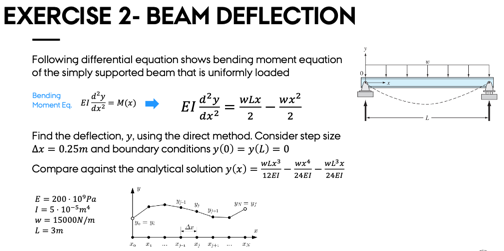

% Solve elastic deflection y(x) of simply supported beam w. uniform load
% EI*y'' = 0.5*wLx - 0.5*wx^2   with BCs:  y(0)=y(L)=0
clc; clear variables; close all;

% parameters in SI units
E = 200e9; % Pa = N/m^2
I = 5e-5; % m^4
L = 3; % m
w = 15000; % N/m

% Boundary Conditions
y0 = 0;
yL = 0;

% discretization
dx = 0.25; 
x  = (0:dx:L)';
nx = length(x);


% setup linear system of finite differences: A*y = b for interior points
n_int = nx-2          % no. interior points

n_int = 11

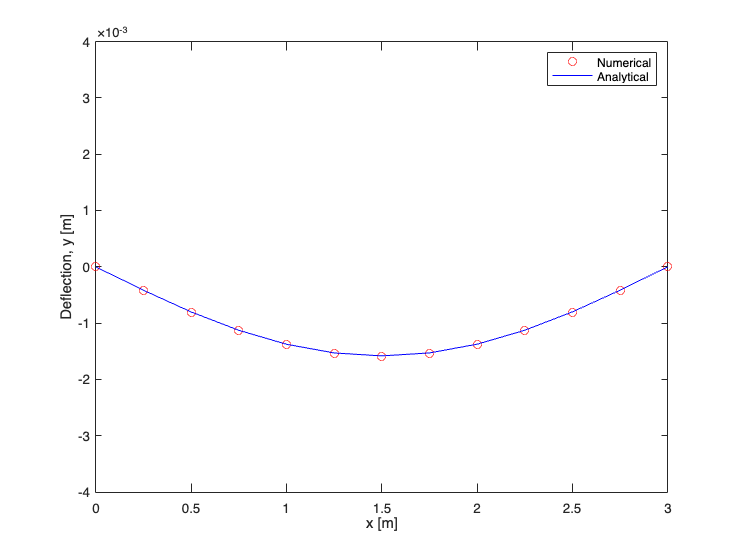

x_int = x(2:end-1);   % vector with internal points x-coordinates
A = zeros(n_int);
b = zeros(n_int,1);

for j = 1:n_int       % row-by-row through interior points
    
    % fill coefficient matrix
    A(j,j) = -2;
    if j>1
        A(j,j-1) = 1;
    end
    if j<n_int
        A(j,j+1) = 1;
    end

    % fill RHS vector
    b(j) = (w*dx^2)/(2*E*I) * (L*x_int(j) - x_int(j)^2);

    if j==1
        b(j) = b(j)-y0/w;
    end
    if j==n_int
        b(j) = b(j)-yL/w;
    end

end

% results array
y = zeros(nx,1); 
y(1)  = y0; % insert boundary values, not really necessary because
y(nx) = yL; % there are zeroes in there already, but as an example.

% solve for interior points 
y(2:nx-1) = A\b; 

% plot & compare with analytical solution
y_analytic = w*L*x.^3/(12*E*I) - w*x.^4/(24*E*I) - w*L^3*x/(24*E*I);

figure
plot(x,y,'or')
hold on
plot(x,y_analytic,'-b')
legend('Numerical','Analytical')
xlabel('x [m]')
ylabel('Deflection, y [m]')
ylim([-4e-3 4e-3])